# AutoDRIVE Ecosystem | Nigel - ROS Bag Data Extraction

## Clear the workspace

close all;
clear;
clc;

## Load the .bag file(s) using GUI prompt

[file_name, path] = uigetfile('*.bag','multiselect','off');
bag_file = rosbag(strcat(path, file_name))

bag_file =   BagSelection with properties:

           FilePath: 'C:\Users\tsamak\Desktop\Nigel System ID\skidpad_rht_0_2.bag'
          StartTime: 1.7044e+09
            EndTime: 1.7044e+09
        NumMessages: 7413
    AvailableTopics: [7×3 table]
    AvailableFrames: {3×1 cell}
        MessageList: [7413×4 table]


## Process the .bag file to extract messages over topics of interest

odometry_selection = select(bag_file,'Topic','/odom');
throttle_selection = select(bag_file,'Topic','/autodrive/nigel_1/throttle_command');
steering_selection = select(bag_file,'Topic','/autodrive/nigel_1/steering_command');

odometry_ts = timeseries(odometry_selection, ...
    'Pose.Pose.Position.X', ...
    'Pose.Pose.Position.Y', ...
    'Pose.Pose.Orientation.X', ...
    'Pose.Pose.Orientation.Y', ...
    'Pose.Pose.Orientation.Z', ...
    'Pose.Pose.Orientation.W', ...
    'Twist.Twist.Linear.X', ...
    'Twist.Twist.Angular.Z' ...
    );
throttle_ts = timeseries(throttle_selection,'Data');
steering_ts = timeseries(steering_selection,'Data');

odometry = odometry_ts.Data;
throttle = throttle_ts.Data;
steering = steering_ts.Data;

## Extract and visualize the physical quantities

- **Throttle (**$\tau$**)**

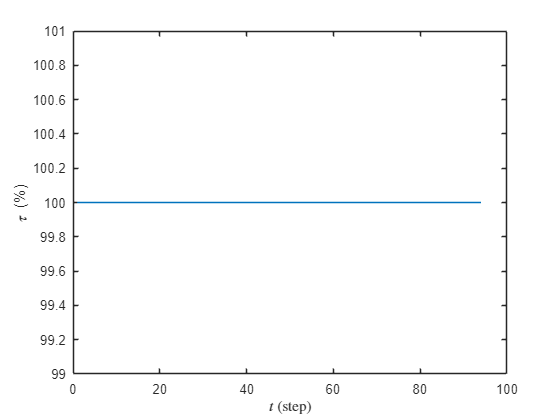

% Synchronize throttle and odometry data
odometry_tsec = second(datetime(odometry_ts.Time,'ConvertFrom','posixtime', 'Format', 'yyyy-MM-dd HH:mm:SSSS'));
throttle_tsec = second(datetime(throttle_ts.Time,'ConvertFrom','posixtime', 'Format', 'yyyy-MM-dd HH:mm:SSSS'));
[unique_elements_odometry,kept_idx,left_idx]=unique_element_finder(odometry_tsec);
[unique_elements_throttle,kept_idx,left_idx]=unique_element_finder(throttle_tsec);

% Find common elements between timeseries objects with cerain tolerance
% straight=7.0e-5, lht_0_1=7.0e-5, lht_0_2=1.48e-4, rht_0_1=3.8e-5, rht_0_2=1.25e-4
common_elements = ismembertol(unique_elements_throttle,unique_elements_odometry,1.25e-4);
[idx_common,val_common] = find(common_elements>0);

% Extract throttle values corresponding to odometry measurements
tau = throttle(idx_common) * 100;

figure()
plot(tau);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('\tau (%)', 'Interpreter', 'tex')

- **Steering (**$\delta$**)**

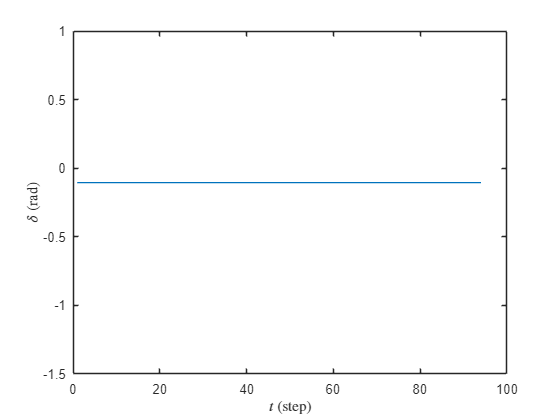

% Synchronize steering and odometry data
odometry_tsec = second(datetime(odometry_ts.Time,'ConvertFrom','posixtime', 'Format', 'yyyy-MM-dd HH:mm:SSSS'));
steering_tsec = second(datetime(steering_ts.Time,'ConvertFrom','posixtime', 'Format', 'yyyy-MM-dd HH:mm:SSSS'));
[unique_elements_odometry,kept_idx,left_idx]=unique_element_finder(odometry_tsec);
[unique_elements_steering,kept_idx,left_idx]=unique_element_finder(steering_tsec);

% Find common elements between timeseries objects with cerain tolerance
% straight=6.87e-5, lht_0_1=7.8e-5, lht_0_2=1.37e-4, rht_0_1=3.95e-5, rht_0_2=1.23e-4
common_elements = ismembertol(unique_elements_steering,unique_elements_odometry,1.23e-4);
[idx_common,val_common] = find(common_elements>0);

% Extract steering values corresponding to odometry measurements
delta = (steering(idx_common)-0.2) * 0.523599;

figure()
plot(delta);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('$\delta$ (rad)', 'Interpreter', 'latex')

- **Position (**$x, y$**)**

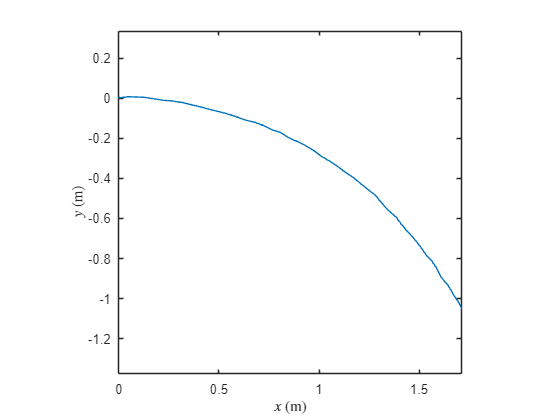

x = odometry(:,1);
y = odometry(:,2);

figure()
plot(x, y)
xlabel('$x$ (m)', 'Interpreter', 'latex')
ylabel('$y$ (m)', 'Interpreter', 'latex')
axis equal
pbaspect([1 1 1])

- **Yaw (**$\psi$**)**

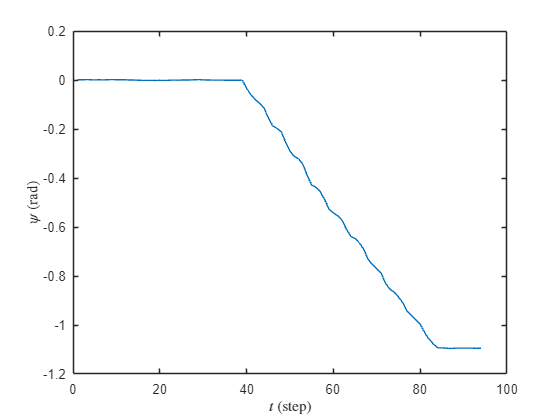

for i=1:size(odometry, 1)
    eul = quat2eul([odometry(i,6) odometry(i,3) odometry(i,4) odometry(i,5)]);
    psi(i) = eul(1);
end
psi = unwrap(psi);

figure()
plot(psi);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('$\psi$ (rad)', 'Interpreter', 'latex')

- **Velocity (**$v$**)**

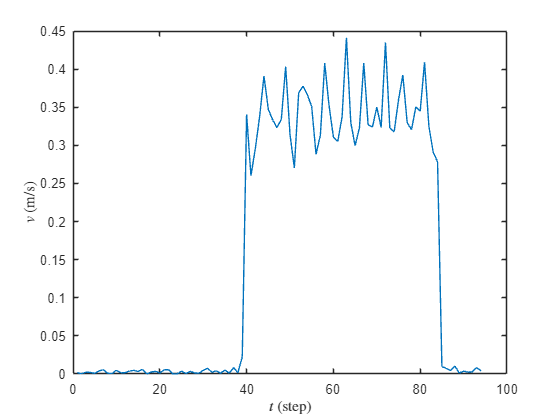

v = abs(odometry(:,7));

figure()
plot(v);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('$v$ (m/s)', 'Interpreter', 'latex')

- **Longitudinal velocity (**$v_x$**)**

                
$$v_x = v*cos(\psi) \approx v$$


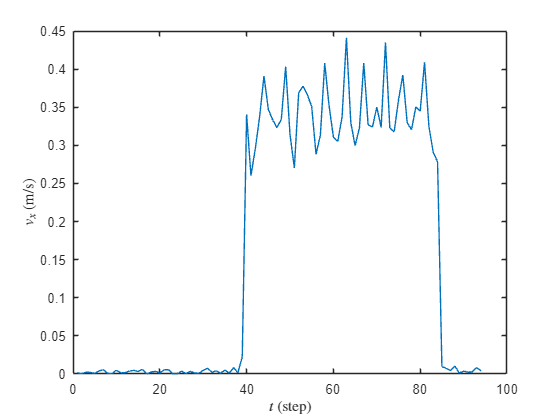

v_x = v;

figure()
plot(v_x);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('$v_x$ (m/s)', 'Interpreter', 'latex')

- **Lateral velocity (**$v_y$**)**

                
$$v_y = v*sin(\psi) \approx v*\psi$$


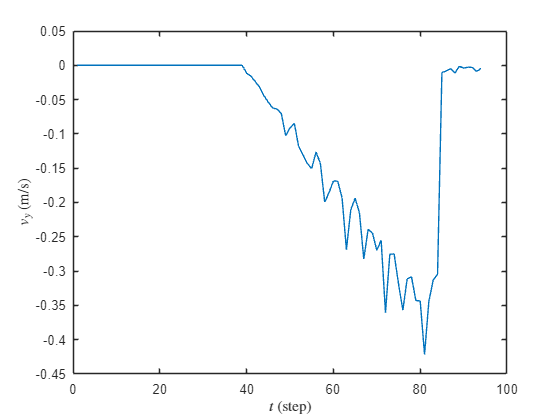

v_y = v.*psi';

figure()
plot(v_y);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('$v_y$ (m/s)', 'Interpreter', 'latex')

- **Angular velocity (**$\dot{\psi}$**)**

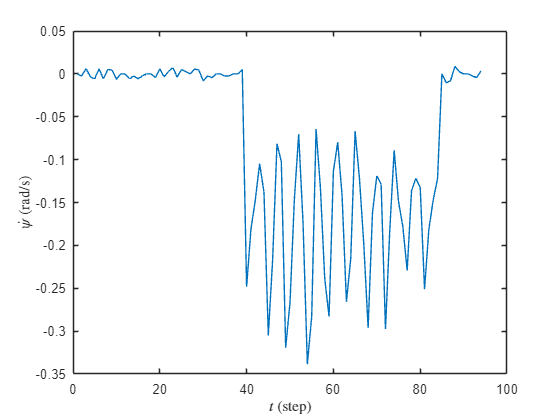

psi_dot = odometry(:,8);

figure()
plot(psi_dot);
xlabel('$t$ (step)', 'Interpreter', 'latex')
ylabel('$\dot{\psi}$ (rad/s)', 'Interpreter', 'latex')

## Downsample data for steady state region

Rename variables according to the .bag file

idx = 59; % straight=60, lht_0_1=47, lht_0_2=63, rht_0_1=61, rht_0_2=59
delta_rht_0_2 = delta(idx);
tau_rht_0_2 = tau(idx);
v_rht_0_2 = v(idx);
v_x_rht_0_2 = v_x(idx);
v_y_rht_0_2 = v_y(idx);
psi_rht_0_2 = psi(idx);
psi_dot_rht_0_2 = psi_dot(idx);

## Save extracted data to .mat file

Rename variables according to the .bag file

%save(strcat(path, file_name(1:end-4),'.mat'),'delta_rht_0_2','tau_rht_0_2','v_rht_0_2','v_x_rht_0_2', 'v_y_rht_0_2', 'psi_rht_0_2', 'psi_dot_rht_0_2');